% data = [PASTE DATA HERE];
% speed_left = data(:,1)
% speed_right = data(:,2)
% time = linspace(0, 3000, 3000/20+1)'
% time = time(:, 1:141) / 1000; % shorten to match speed data, convert ms to s
% save("motor_calibration_data2", "speed_left", "speed_right", "time")

load("motor_calibration_data2")
load("motor_calibration_data")

We are trying to solve for coefficients needed in M(s) motor control block, given as M(s) = V(s)/Vc(s), where V(s) is the velocity of each wheel, and Vc(s) is the velocity control signal coming from the PI controller K(s). 

The motor input signal we gave to collect this calibration data was a step input with a constant magnitude of 300. We could either consider Vc(t) to equal 300 in this case, or we could consider Vc(t) to equal 1 and 300 to be a baseline motor input which K will scale.

Either way, in the time domain V(s) is v(t) = 300*K*(1-exp(-t/tau)) for this case and we can fit the collected speed data for the right and left wheel to this function. Units of axes are speed [m/s] and time [s].

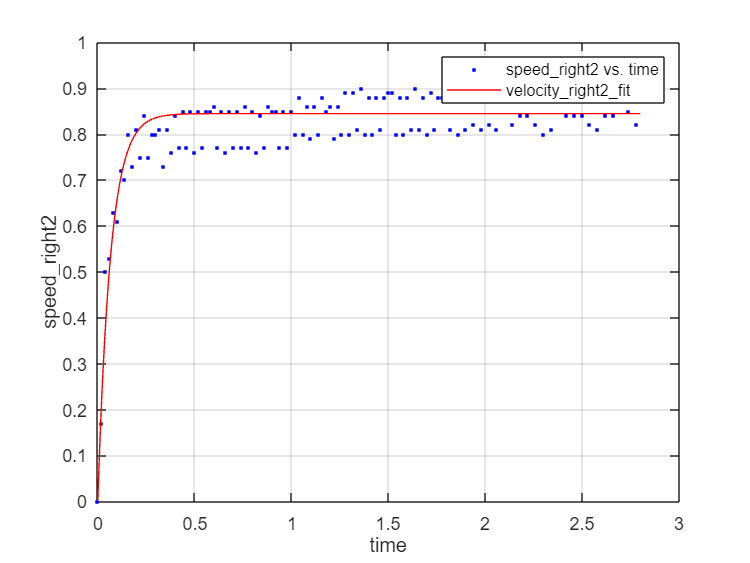

velocity_left = expFit(time, speed_left);

K_left = velocity_left.K

K_left = 0.0028

tau_left = velocity_left.tau

tau_left = 0.0661

K_left/300

ans = 9.3836e-06

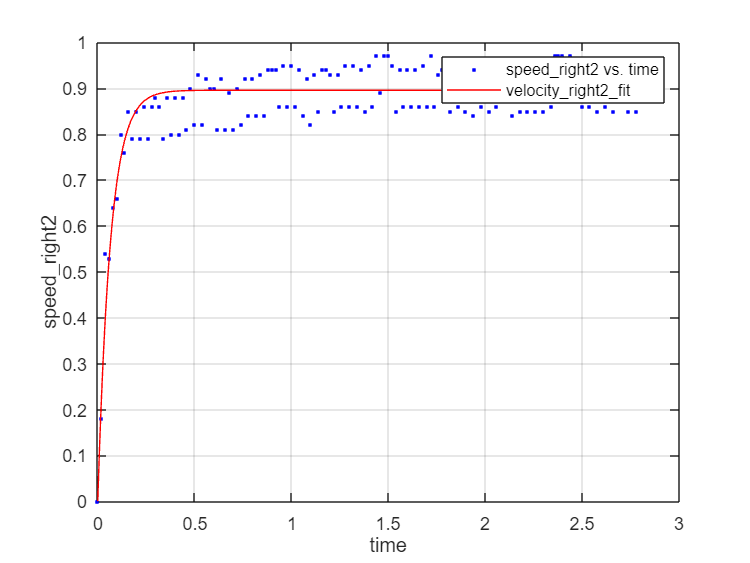

velocity_right = expFit(time, speed_right);

K_right = velocity_right.K

K_right = 0.0030

tau_right = velocity_right.tau

tau_right = 0.0659

K_right/300

ans = 9.9495e-06

function [fitresult, gof] = expFit(time, speed)
%  Create a fit.
%
%  Data for 'velocity_fit' fit:
%      X Input: time
%      Y Output: speed
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.

%% Fit: 'velocity_fit'.
[xData, yData] = prepareCurveData( time, speed );

% Set up fittype and options.
ft = fittype( '300*K*(1-exp(-t/tau))', 'independent', 't', 'dependent', 'v' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.002 60/1000];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'velocity_right2_fit' );
h = plot( fitresult, xData, yData );
legend( h, 'speed_right2 vs. time', 'velocity_right2_fit', 'Location', 'NorthEast', 'Interpreter', 'none' );

% Label axes
xlabel( 'time', 'Interpreter', 'none' );
ylabel( 'speed_right2', 'Interpreter', 'none' );
grid on

end